# Hill kinetics demo

This is a demonstration of the Hill-type kinetics in the differential equation for per mRNA from the Goldbeter (1995) model of PER by Gabrielle Gutierrez, PhD for CAMP 2023.


$$dM/dt = v_s \frac{K_I^n}{K_I^n + P_N^n} - v_m \frac{M}{K_m + M} = {term}_1 - {term}_2$$


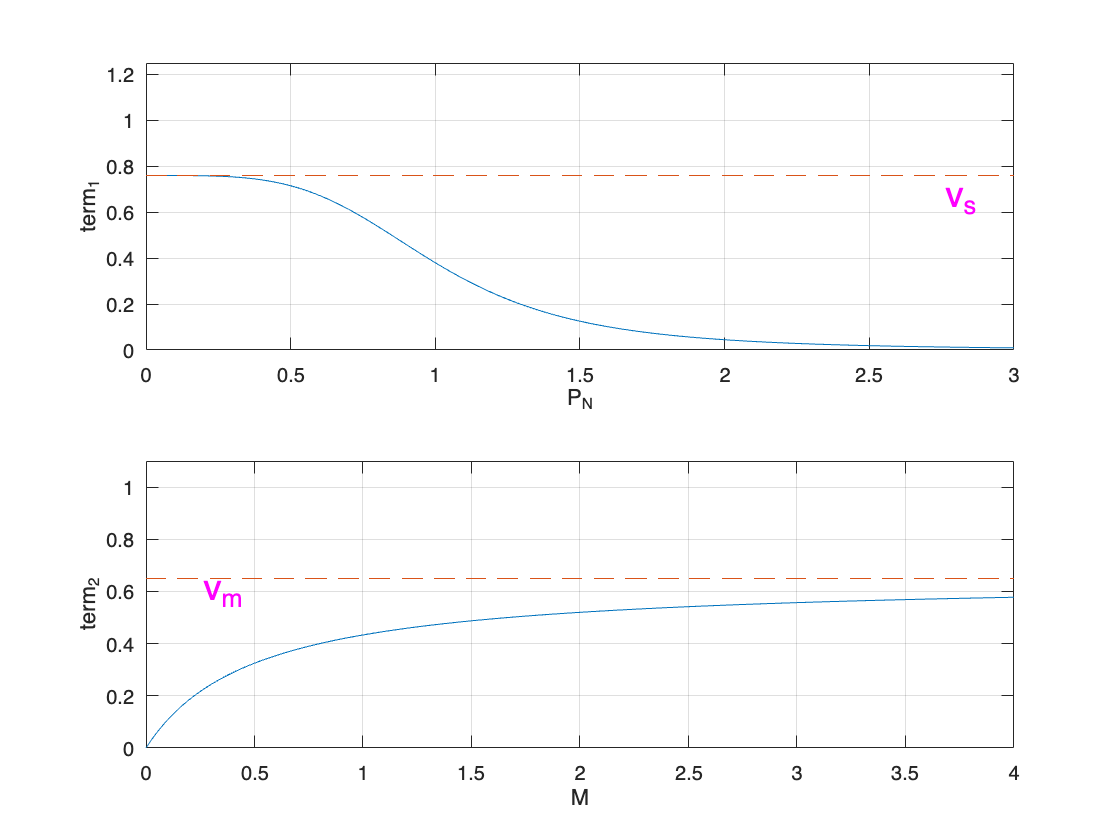

M = 0:0.02:4;
PN = 0:0.02:3;

v_s = 0.76; %microM/h
v_m = 0.65; %microM/h
K_m = 0.5; %microM
K_I = 1; %microM
n = 4;

term1 = v_s.*(K_I^n)./(K_I^n + PN.^n);
term2 = v_m.*M./(K_m + M);

figure;
subplot(2,1,1)
plot(PN,term1)
hold on 
plot(PN,v_s.*ones(size(PN)),'--')
xlabel('P_N')
ylabel('term_1')
text(2.75,v_s-0.1,'v_s','FontSize',18,'Color','magenta')
grid on
ylim([0 1.25])

subplot(2,1,2)
plot(M,term2)
hold on 
plot(M,v_m.*ones(size(M)),'--')
xlabel('M')
ylabel('term_2')
text(0.25,v_m-0.05,'v_m','FontSize',18,'Color','magenta')
grid on
ylim([0 1.1])

Try experimenting with each term individually by varying the parameters. What does each parameter control?

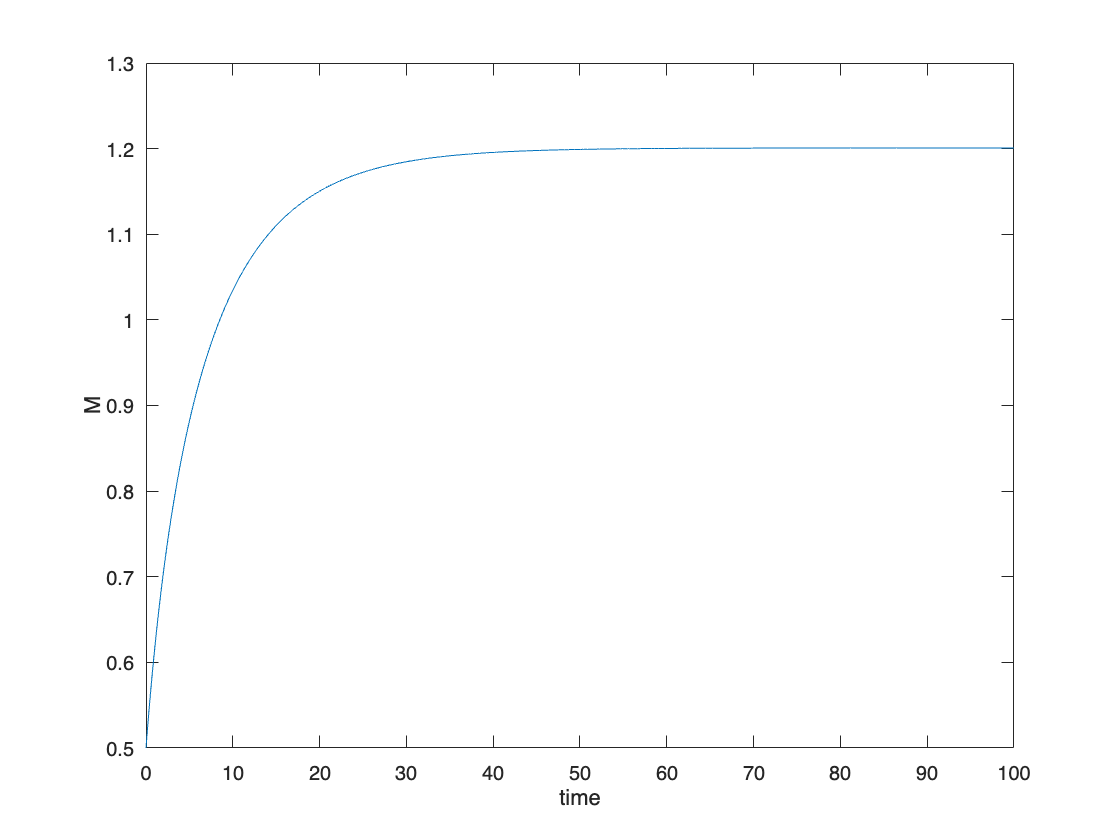

dt = 0.01;
time = 0:dt:100;
M = zeros(size(time));

PNconc = 0.9;
M_init = 0.5;

M(1) = M_init;

for t = 1:length(time)-1
    dM = dt*((v_s.*(K_I^n)./(K_I^n + PNconc.^n)) - (v_m.*M(t)./(K_m + M(t))));
    M(t+1) = M(t) + dM;
end

figure
plot(time,M)
xlabel('time')
ylabel('M')